# Exercise 2: Test generation from requirements using prompt engineering 

The base of shift-left verification is to start writing the unit test as soon as we get the requirements, even before implementing the logic or developing algorithms. 

For this exercise we will use MATLAB Copilot (AI Assistant) within the MATLAB's environment to generate unit test from the requirements itself. In exercise 1, we have already imported the requirements from an excel sheet into requirement editor tool.  

## Step 1: Open the copilot chat window as shown

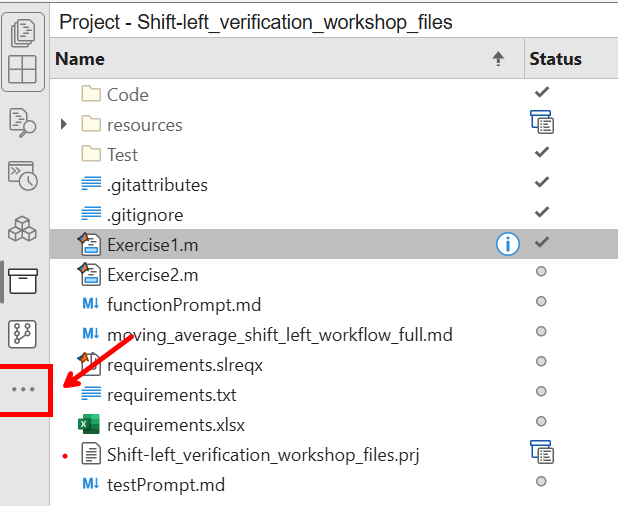

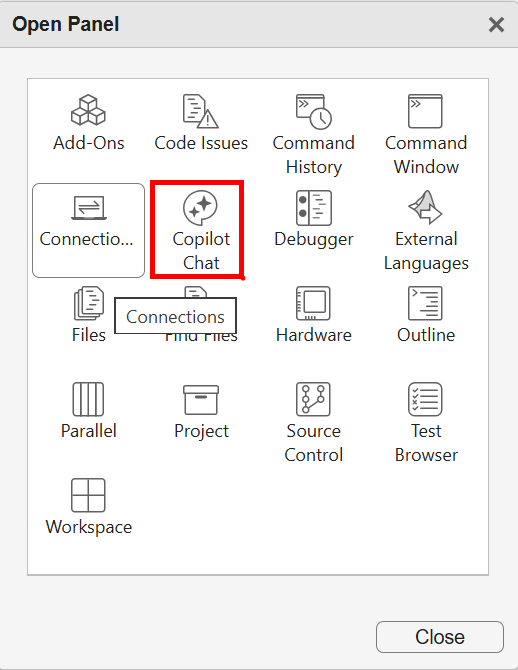

You will see a copilot chat window on the MATLAB environment. 

## Step 2: Understand the prompt

type testPrompt.md


You are acting as a verification engineer.

Using only the requirements below, create a MATLAB unit-test class named `TestMovingAverage.m` for the function `movingAverage`

Requirements:
- R1: y shall have the same size as x
- R2: N shall be a finite, positive integer scalar
- R3: Invalid N values shall produce an error identifier movingAverage:InvalidWindow
- R4: At index k, y(k) shall equal the arithmetic mean of x(max(1,k-N+1):k)
- R5: Before N samples are available, the function shall average all available samples
- R6: A constant input signal shall be preserved
- R7: A row-vector input shall produce a row-vector output
- R8: A column-vector input shall produce a column-vector output

Instructions:
- Use the `matlab.unittest` framework.
- Trace each test to one or more requirement IDs in comments.
- Include nominal, boundary, invalid-input, row-vector, and column-vector cases.
- Use explicitly calculated expected values.
- Verify invalid window lengths using the required error ide

## Step 3: Generate the test file from prompt

Copy the prompt from testPrompt.md and ask copilot to generate the test cases. 

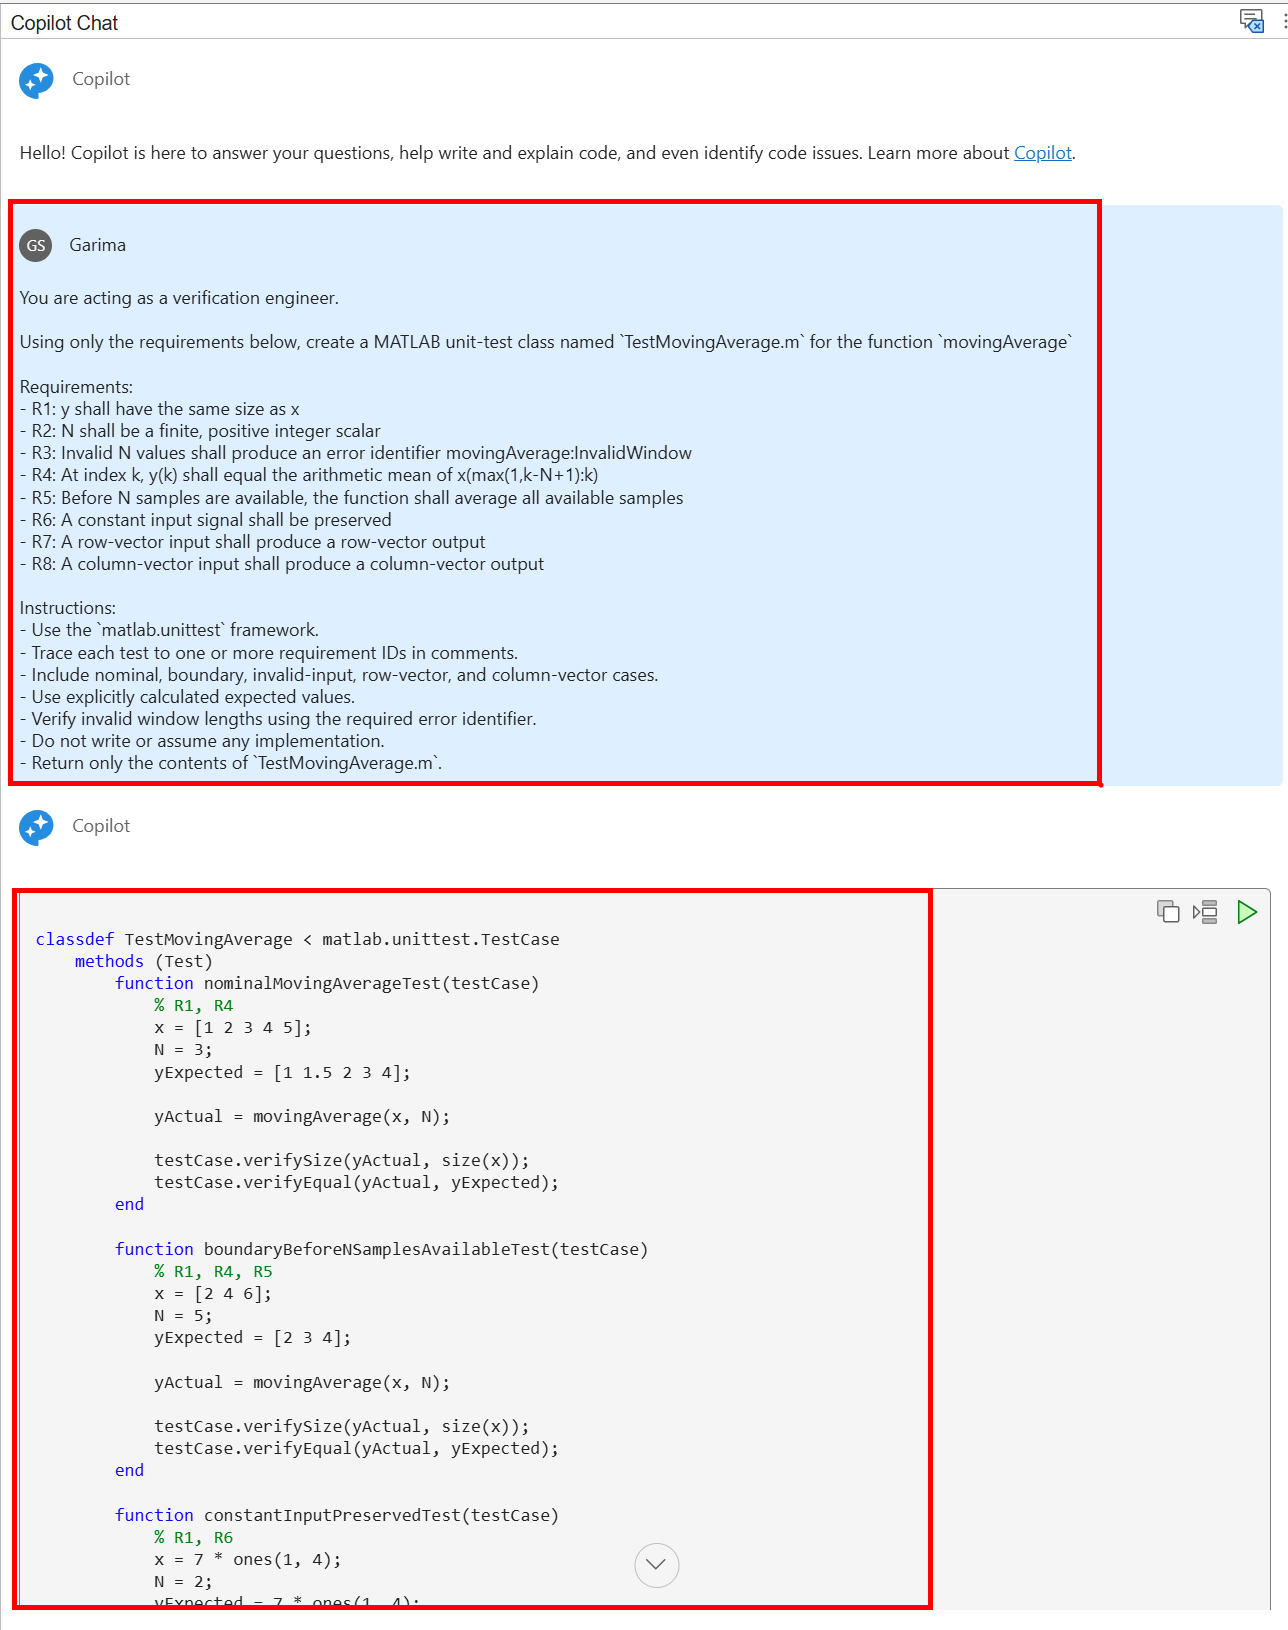

## Step 4: Save the test cases generated by copilot in the Test Folder 

Once the test cases are copied from copilot chat, create a new MATLAB script file and paste the test cases. 

Save as the test cases in folder "Test" with name "TestMovingAverage".

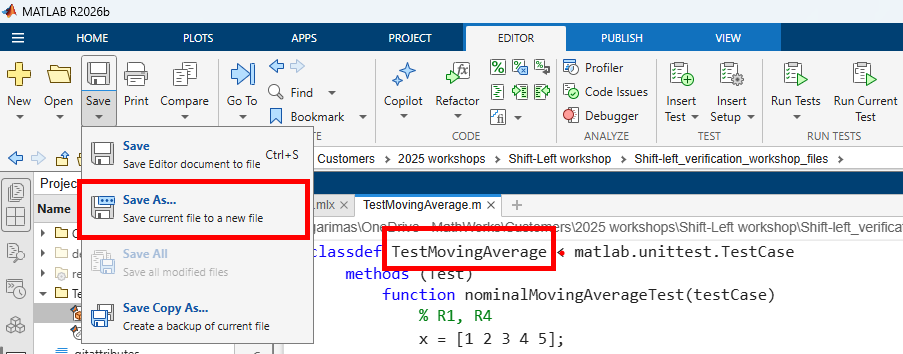

## Step 5: Run test using "Run test" from Editor tab

When the test file is open, use the "Run Tests" button to run the current file of test cases. It will open another window "Test Browser", that reflects the test status of each test case. 

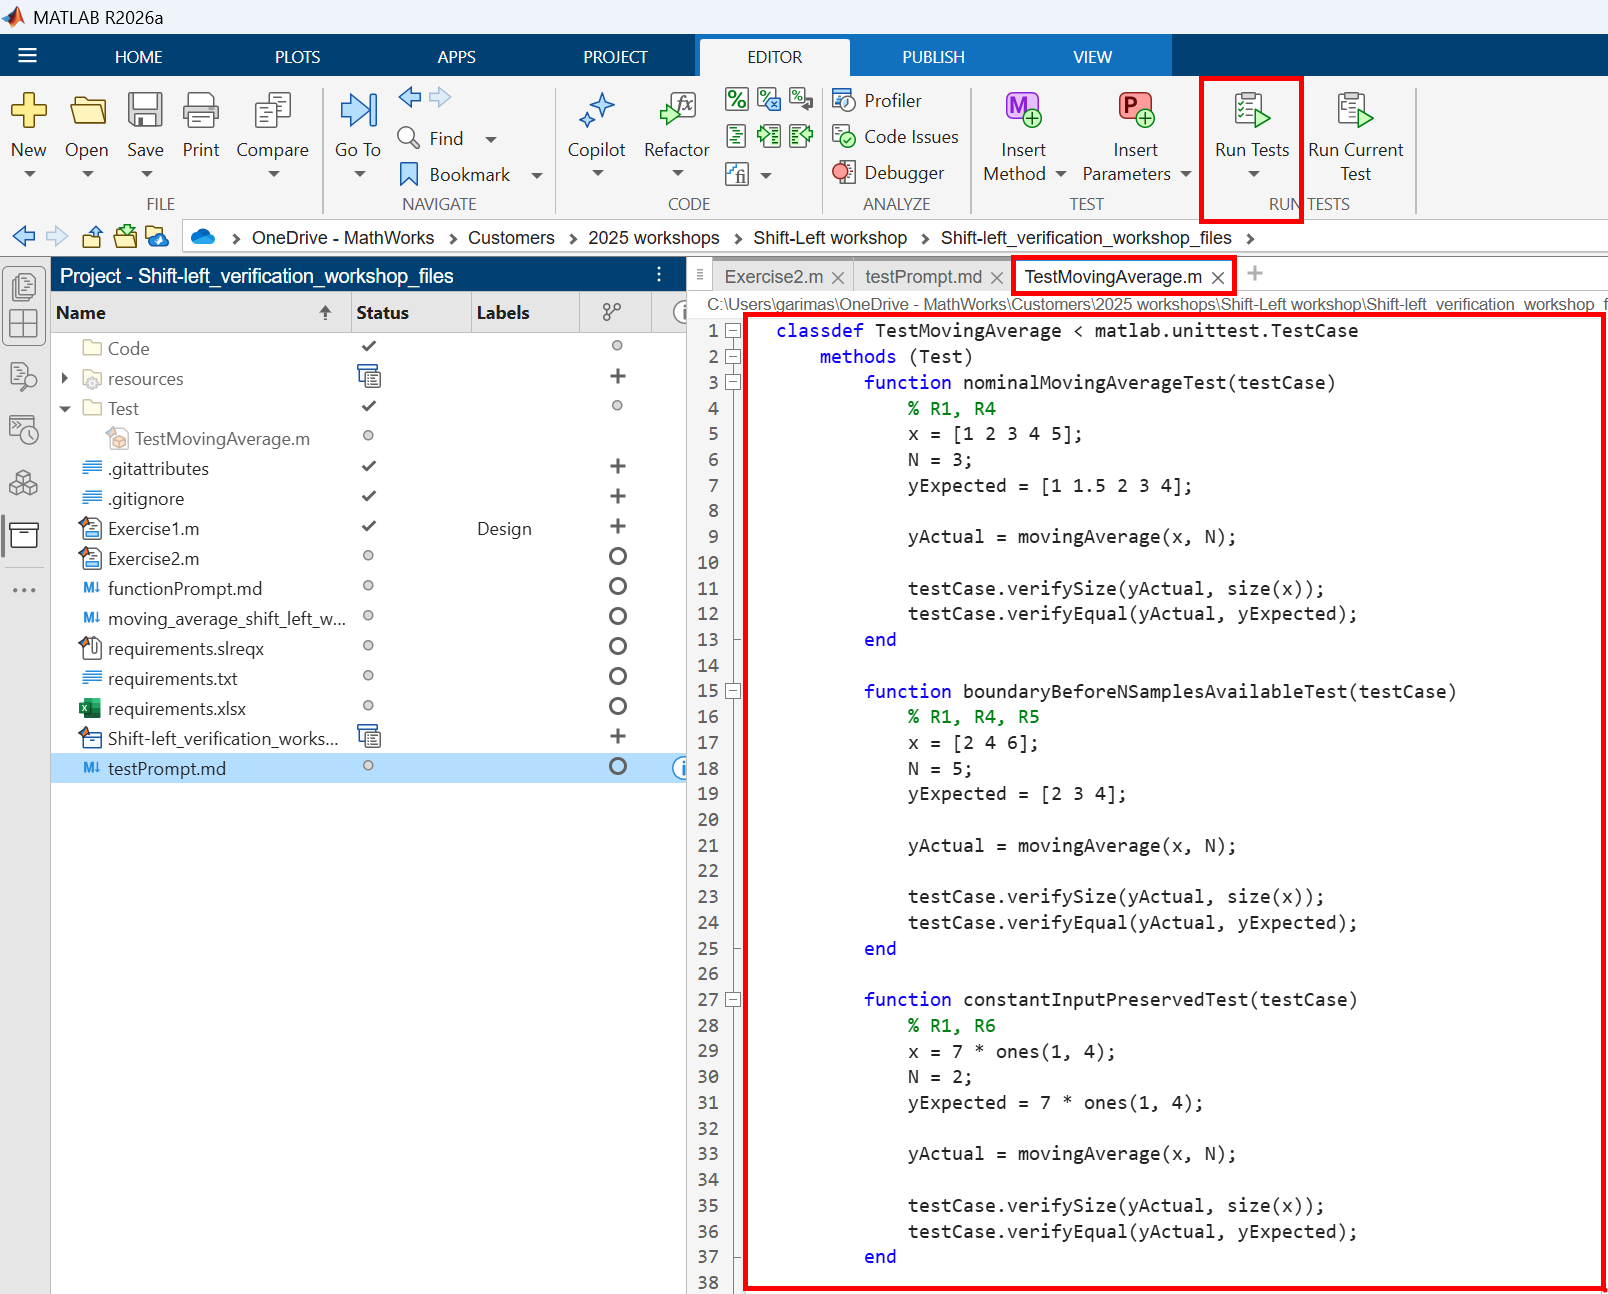

Spend some time to find answers to the questions: 

- Why some test failed? 

- Where to find relevant information like diagnostic reports/errors? 

- How to navigate with other options in " Test Browser"? 

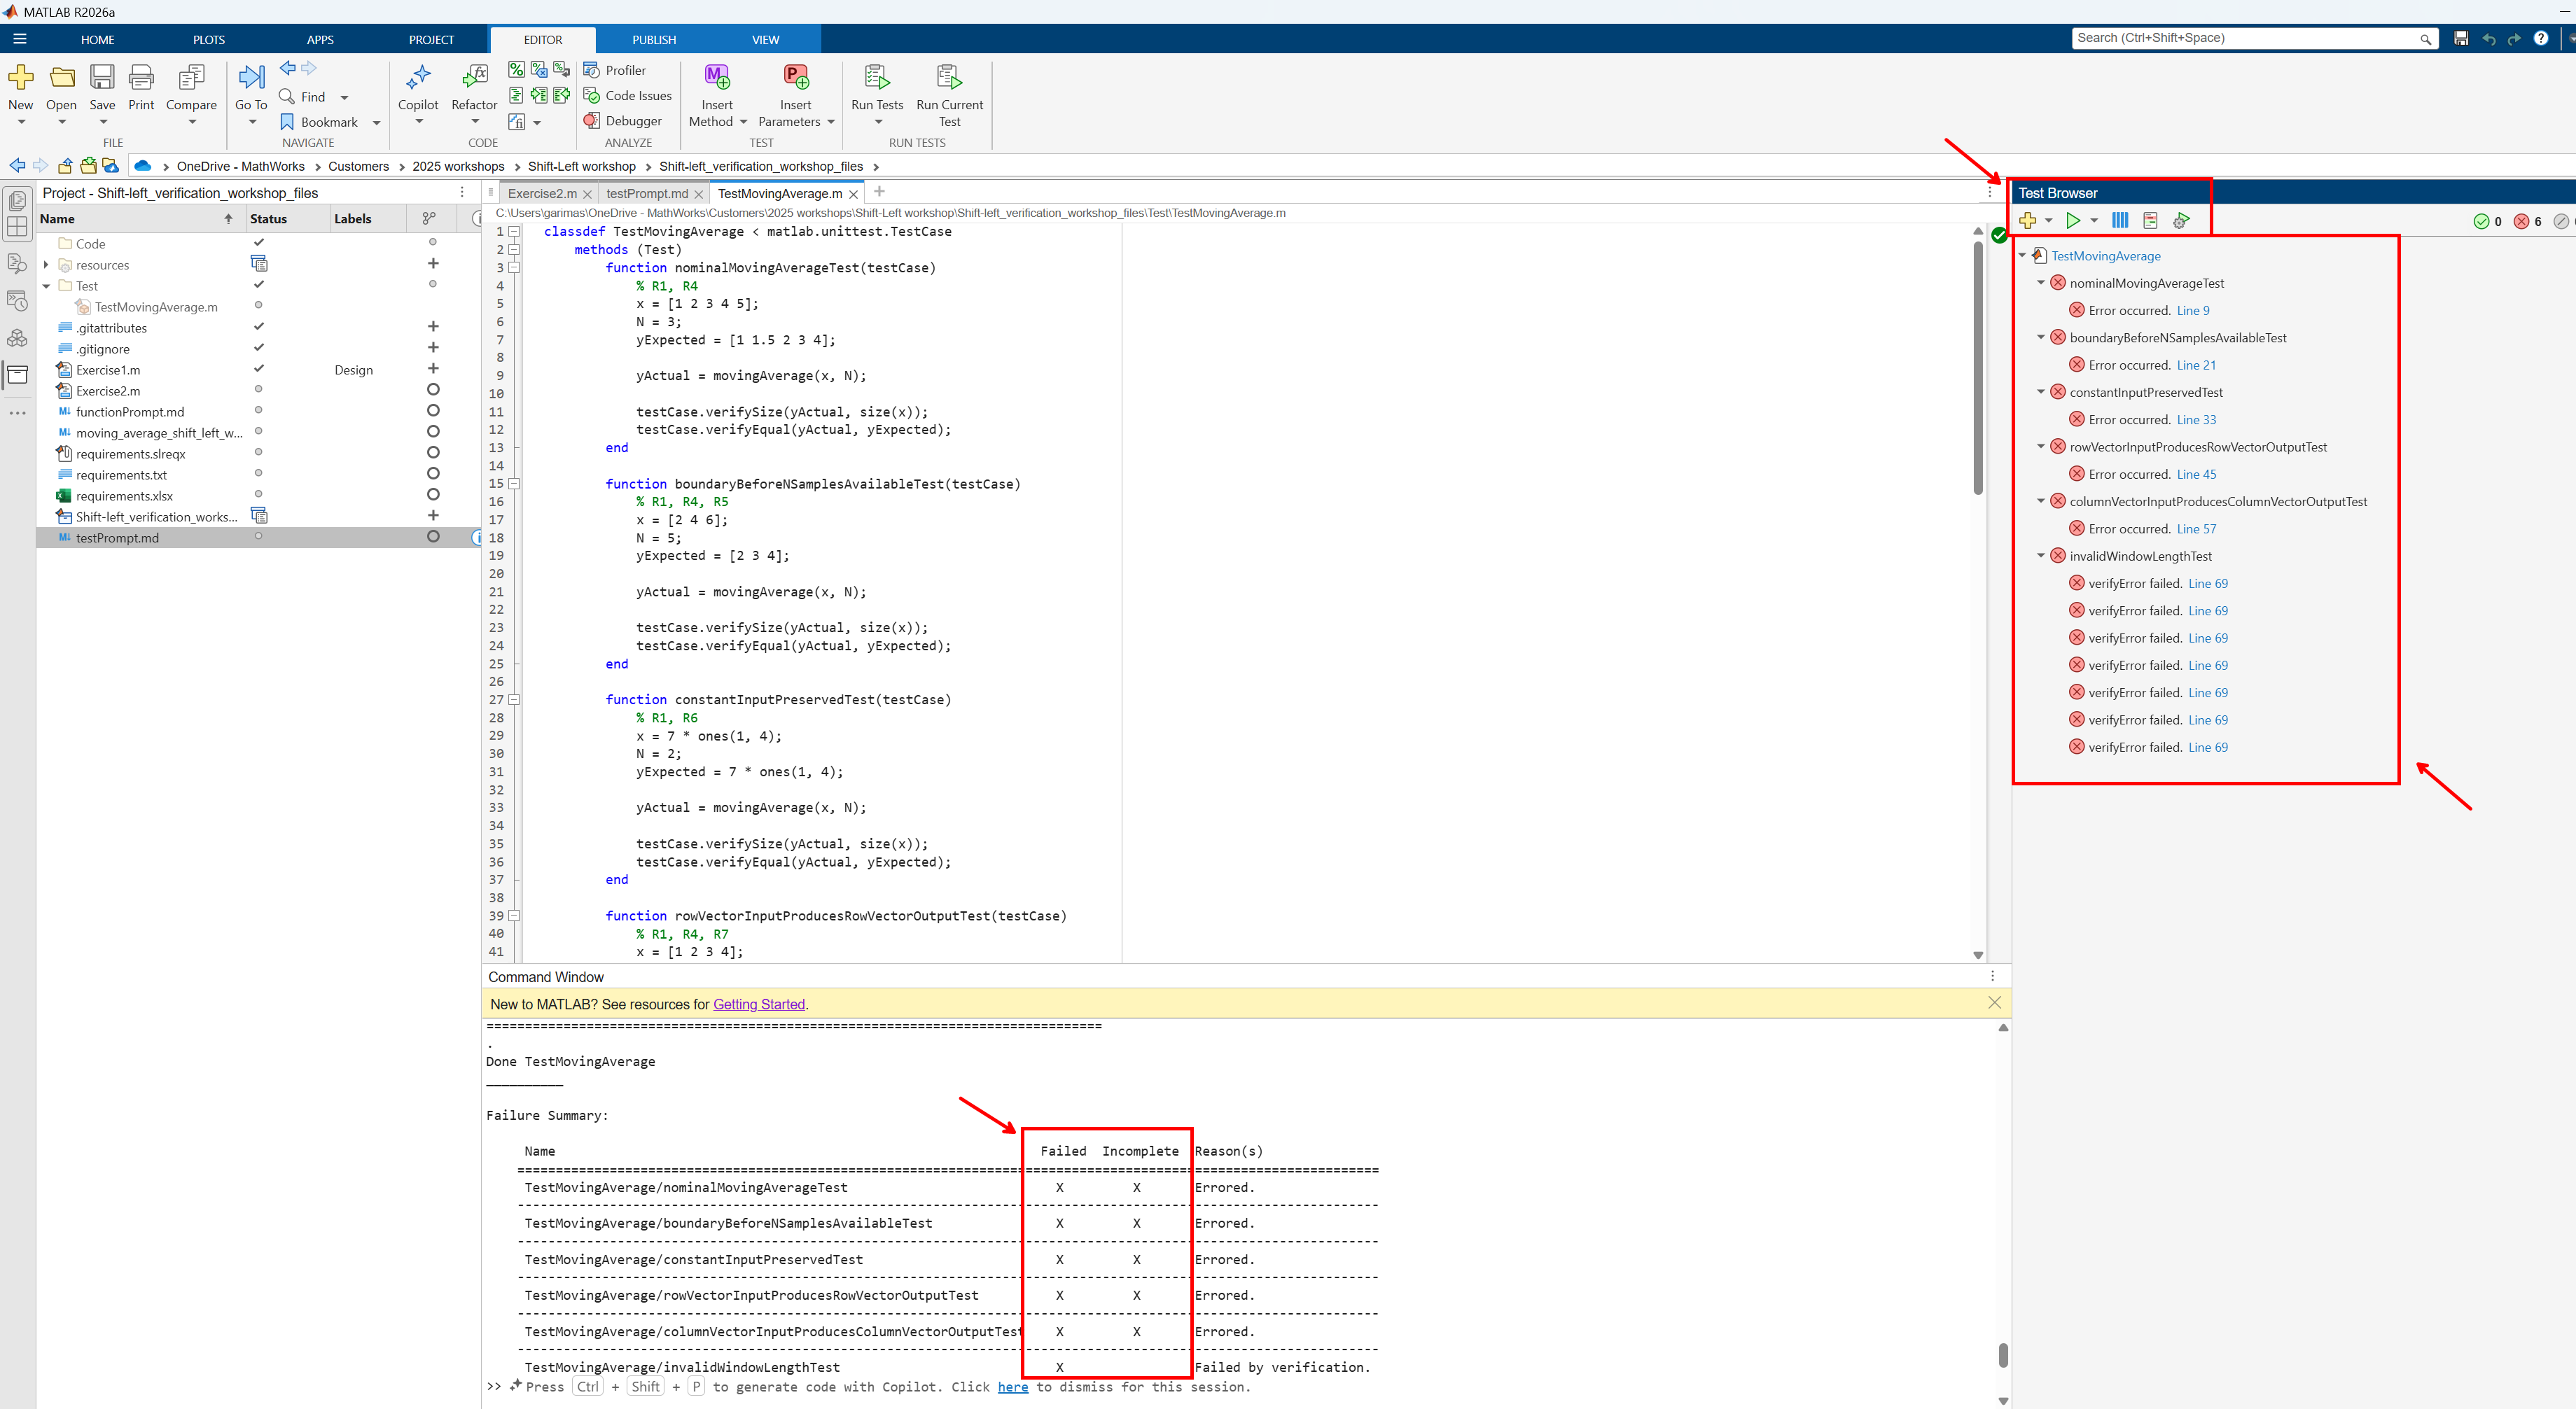

**Make sure to add Test folder and its subfolders to project**